# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu

Max Planck - University of Toronto Centre

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de}

Version: 250731

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1), the post-op CT scan (hereafter referred to as CT), and *optionally, the pre-op T2-weighted MRI scan (hereafter referred to as T2)*. The scans should be in DICOM (.dcm) or NIFTI (.nii) format.

- Make sure that .dcm files in one folder all belong to the same scan (i.e., create dedicated T1/T2/CT folders when preparing DICOM files)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

cfg.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

cfg.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

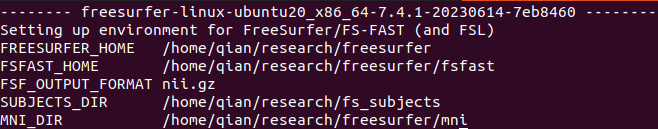

Type patient ID below:

pat.id  = "TWH";

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
cfg.dir_el          = strjoin(elec_loc_path_parts(1:end-1), filesep);
addpath(fullfile(cfg.dir_el, 'functions'))
[cfg, pat] = el_init(cfg, pat);

## Import and preprocess scans

Say goodbye to manual preprocessing and coregistration of anatomical scans! The script here imports the T1, CT (and optionally T2) scans into a FreeSurfer subject folder. Moreover, it performs automatic AC-PC alignment, coregistration, and defacing. The resulting scans are ready for electrode localization and data sharing.

### Procedure

- Run this section.

- ([UI prompt] [If preprocessed files already exist in the output folder] Indicate whether you want to re-import and re-preprocess the scans. If you choose no, the section will simply read and print the paths to preprocessed scans

- [UI prompt] Indicate whether you want to import DICOM or NIFTI files.

- [UI file/directory selection] Select T1, CT (and T2) one by one according to prompt in the dialog title. For DICOM, you need to select a folder containing all .dcm files corresponding to one scan. For NIFTI, you need to select a single .nii file.

- Wait for processing. During CT processing, a viewer window will pop up to let you inspect the CT scan. You can adjust the minimum value to roughly determine an intensity threshold such that only bones and electrodes are visible to effectively de-identify the patient. Enter the value into the textbox.

- A viewer window will pop up at the end to allow you to inspect the scans overlaid on top of grayscale T1. The scans should be aligned to each other and defaced. Close the window when done inspecting.

### Output

- The elec_loc subfolder (`pat.dir.el`) in FreeSurfer subject folder with preprocessed (AC-PC aligned, defaced, and co-registered) scans. Scan file names comply with BIDS format (e.g., *sub-XXX_acq-preop_T1w.nii*). Compressed scans (.nii.gz) are further available in elec_loc/BIDS_outputs/anat.

- Updated `pat` structure.

pat = el_import_scans(pat, cfg);

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section launches iElectrodes.    

cd(pat.dir.el)
electrodes_gui

### iElectrodes toolbars

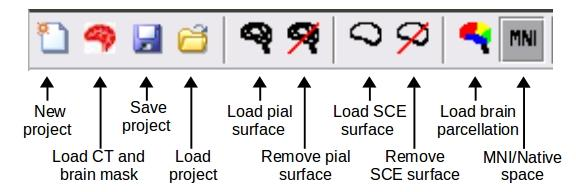

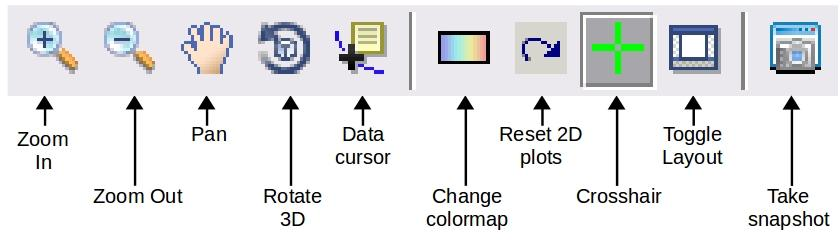

### Steps

- Click "New project" (see icon above) and load *sub-XXX_T1w.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan *sub-XXX_CT.nii.*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- When you are done, save the project (see icon above) and name it as *sub-XXX.iel*. You can also save the project halfway and reload it using the "Load project" button.

## FreeSurfer recon-all with optional subregion segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

`recon-all` is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

Subsequently, users can also choose to perform subregion segmentation, including the [hippocampus/amygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala) and [thalamus](https://surfer.nmr.mgh.harvard.edu/fswiki/ThalamicNuclei).

### Inputs

- [Auto-loaded] Defaced, AC-PC aligned T1 (and T2)

- [Select from dropdown box] whether to perform hippocampus/amygdala and/or thalamus subregion segmentation.

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

segment_amygdala_hippocampus = true;
segment_thelamus = false;
el_fs_recon_all(cfg, pat, segment_amygdala_hippocampus, segment_thelamus)

## Convert .mgz to .nii and create bilateral meshes

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in FreeSurfer *mri* subfolder

- [Auto-loaded] xh.white and xh.pial.T1 files in FreeSurfer *surf* subfolder

### Outputs

- .nii files in FreeSurfer *mri* subfolder

- bil_white.nv and bil_pial.nv in *elec_loc* subfolder

el_mgz2nii(cfg, pat)
el_merge_mesh(pat)

## Read localization results from .iel

### Input

- [Select from GUI] iElectrodes project .iel file

### Output

- Updated `pat` structure with new field `elec`

pat = el_get_elec(pat);

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- Updated MATLAB structure `elec` with microwires

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3.75;
pat.elec = el_est_micro(pat.elec, micro_to_macro_dist);

## [If re-referencing with bipolar setup] Estimate virtual electrode location

Estimate the middle point between adjacent contacts for each depth electrode and add it to the electrodes structure with type `bipolar`

### **Input**

- [Auto-loaded] MATLAB structure `elec`

### **Output**

- Updated MATLAB structure `elec` with virtual electrodes

pat.elec = el_bipolar(pat.elec);

## Visualize electrode locations on native T1 and CT

### Output

- Figures for each channel in the subfolder *elec_loc/slice_views*

el_slice_view(pat)

## Get FreeSurfer labels in the native space

The main purpose of running FreeSurfer recon-all is to produce automated cortical parcellation. By combining electrode location with the parcellations, we can automatically assign them anatomical labels. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.)

The output filenames are BIDS-compliant ([https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv](https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv)). Since results from this section are derived from the patient's native space (which is ACPC aligned), the identifier is `sub-xxx_space-ACPC_electrodes`.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] FreeSurfer parcellation files 

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get FreeSurfer label with iElectrodes' `anatomicLabelFS` function

- Expand to also get hippocampal subfield labels

el_elec_native(cfg, pat)

## Get electrode coordinates in MNI152 space

For group-level visualization of electrode location, mapping locations from native to standardized spaces is necessary. This section does a linear transform to electrode locations to map them to the MNI152 (ICBM152) space.

[https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin](https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin)

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] T1 scan to be registered to MNI152Lin template

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get Harvard-Oxford atlas labels with iElectrodes' `anatomicLabel` function

- Get other labels for the MNI space (e.g. AAL)

el_elec_mni152(cfg, pat)